## **PL 2 Probabilidade, Probabilidade Condicional e Independência**

### **2.1. Probabilidade**

**3. Array de tamanho T que serve de base à implementação de uma memória associativa. A função hash devolve um valor entre 0 e T-1 com todos os valores equiprováveis.**

a) Probabilidade de colisão com 10 keys e T = 1000

T = 1000;
k = 10;
numExp = 10000;
casosFav_a = 0;

% prob teórica:
probNaoColisaoT = 1;
for i = 1:k-1
    probNaoColisaoT = probNaoColisaoT * (T-i)/T;
end
probColisaoT = 1 - probNaoColisaoT

probColisaoT = 0.0441

%

% prob experimental:
for i = 1:numExp
    matrizKeys = randi(T,1,k);
    if length(matrizKeys) > length(unique(matrizKeys))
        casosFav_a = casosFav_a + 1;
    end
end
probColisao_a = casosFav_a/numExp

probColisao_a = 0.0427

b) gráfico da probabilidade de a) em função do nº de keys (valores relevantes num array com T = 1000)

vetorK = [1:2:10,20:20:100,150,200:100:500,750,1000];

vetorK =            1           3           5           7           9          20          40          60          80         100         150         200         300         400         500         750        1000


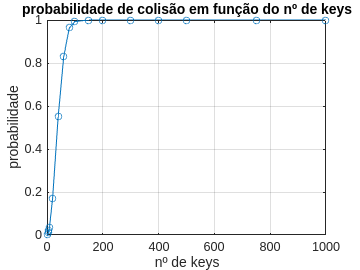

T = 1000;
numExp = 1e4;
vetorProbColisao = zeros(1,length(vetorK));

for numKeys = 1:length(vetorK)
    casosFav_b = 0;
    for i = 1:numExp
        matrizKeys = randi(T,1,vetorK(numKeys));
        if length(matrizKeys) > length(unique(matrizKeys))
            casosFav_b = casosFav_b + 1;
        end
    end
    probColisao = casosFav_b/numExp;
    vetorProbColisao(numKeys) = probColisao;
end

% gráfico
plot(vetorK,vetorProbColisao,Marker='o',MarkerSize=5)
title('probabilidade de colisão em função do nº de keys');
xlabel('nº de keys');
ylabel('probabilidade')
grid on;

%

c) gráfico da probabilidade de **não** haver nenhuma colisão em função do tamanho de T (vetor 100:100:1000) - 50 keys

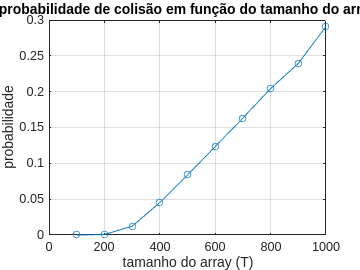

k = 50;
vetorT = 100:100:1000;
numExp = 1e4;
vetorProbNaoColisao = zeros(1,length(vetorT));

for sizeT = 1:length(vetorT)
    casosFav_c = 0;
    for i = 1:numExp
        matrizT = randi(vetorT(sizeT),1,k);
        if length(matrizT) == length(unique(matrizT))
            casosFav_c = casosFav_c + 1;
        end
    end
    probNaoColisao = casosFav_c/numExp;
    vetorProbNaoColisao(sizeT) = probNaoColisao;
end

% gráfico
plot(vetorT,vetorProbNaoColisao,Marker='o',MarkerSize=5)
title('probabilidade de colisão em função do tamanho do array');
xlabel('tamanho do array (T)');
ylabel('probabilidade')
grid on;

%